# Equilibrium point / Transfer function ( p1)

## **Defining Variables**

clear; clc; close all;

syms G X I U D
Gb = 4.5;
Ib = 15;
P1 = 0;
P2 = 0.025;
P3 = 0.000013;
V = 12;
n = 5.54/60;
F = [ -P1*G-X*(G+Gb)+D;
      -P2*X+P3*I;
      -n*(I+Ib)+U/V ];
y = G;

St = [G;X;I];
In = [U;D];

## **Equilibrium State**


% sol_s = solve(subs(F,{D},{0})==[0;0;0], [G,X,I]);
% Ge = sol_s.G; Ie = sol_s.I; Xe = sol_s.X;
St_e = [0;0;0];
In_e = [n*Ib*V;0];
Fe = subs(subs(F,In,In_e),St,St_e);

## Linearize


% f(x) = f(xe,ue) + (grad(f,x)|x=xe,u=ue)*(x-xe) + (grad(f,u)|x=xe,u=ue)*(u-ue)
grad_F_St = [ diff(F(1),St(1)), diff(F(1),St(2)), diff(F(1),St(3));
              diff(F(2),St(1)), diff(F(2),St(2)), diff(F(2),St(3));
              diff(F(3),St(1)), diff(F(3),St(2)), diff(F(3),St(3)) ];
grad_F_In = [ diff(F,In(1)) , diff(F,In(2)) ];
A = double(subs(subs(grad_F_St,In,In_e),St,St_e))

A =          0   -4.5000         0
         0   -0.0250    0.0000
         0         0   -0.0923


B = double(subs(subs(grad_F_In,In,In_e),St,St_e))

B =          0    1.0000
         0         0
    0.0833         0


C = [1,0,0]

C =      1     0     0


D = 0

D = 0

## Transfer Function


syms s
n = size(A,1);
Gp = C*inv(s*eye(n)-A)*B;
ExpFun = matlabFunction(simplifyFraction(Gp,'Expand',true));
ExpFun = str2func(regexprep(func2str(ExpFun), '\.([/^\\*])', '$1'));
Gp = tf(ExpFun(tf('s')));
for i = 1:length(Gp)
    [num,den] = tfdata(Gp(i));
    Gp(i) = tf(num{1}/den{1}(1),den{1}/den{1}(1));
end
Gp = Gp(1)


Gp =
 
           -4.875e-06
  -----------------------------
  s^3 + 0.1173 s^2 + 0.002308 s
 
Continuous-time transfer function.



[Gp_Num, Gp_Den] = tfdata(Gp);

# Analog Control(p2)


Gc = pidtune(Gp,'PID')


Gc =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = -22.7, Ki = -0.0995, Kd = -1e+03
 
Continuous-time PID controller in parallel form.



trans_info = stepinfo(feedback(series(Gc,Gp),1))

trans_info = struct with fields:
        RiseTime: 29.3956
    SettlingTime: 405.7572
     SettlingMin: 0.9186
     SettlingMax: 1.0793
       Overshoot: 7.9320
      Undershoot: 0
            Peak: 1.0793
        PeakTime: 66.0147


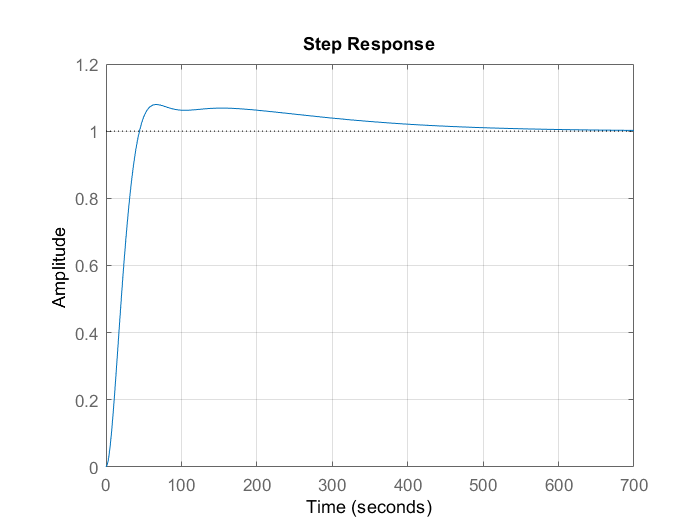

step(feedback(series(Gc,Gp),1))
grid on

# Digital Control (P3) // Should be completed by arman barghi

% 2 < tr/Ts < 10
Ts = round(trans_info.RiseTime/8)

Ts = 4

Gd_1 = c2d(Gc,Ts,'tastin')


Gd_1 =
 
            Ts*(z+1)        2*(z-1) 
  Kp + Ki * -------- + Kd * --------
            2*(z-1)         Ts*(z+1)

  with Kp = -22.7, Ki = -0.0995, Kd = -1e+03, Ts = 4
 
Sample time: 4 seconds
Discrete-time PID controller in parallel form.



Gd_2 = c2d(Gc,Ts,'matched')


Gd_2 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = -23.1, Ki = -0.0994, Kd = -1.05e+03, Ts = 4
 
Sample time: 4 seconds
Discrete-time PID controller in parallel form.



# **Discrete Transfer Function( p4 )**

**Using Theoretical Calculations :**


$$\begin{array}{l}
\mathrm{Using}\text{ }\mathrm{Mathematica}\\
\text{Simplify}\left\lbrack \text{InverseLaplaceTransform}\left\lbrack -4.875\ast 10ˆ-6/\left(sˆ2\ast \left(sˆ2+0.1173\ast s+0.002308\right)\right),s,t\right\rbrack //N\right\rbrack \\
-0.00211\text{}t+0.0085\text{}e^{-0.0923 t} -0.115856\text{}e^{-0.025 t} +0.1073
\end{array}$$



$$\text{Simplify}\left\lbrack \left(1-zˆ-1\right)\ast \left(0.10735/\left(1-zˆ-1\right)-0.0021122\ast z/\left(z-1\right)ˆ2+0.00850593/\left(1-\text{Exp}\left\lbrack -0.0923\ast 4\right\rbrack \ast zˆ-1\right)-0.115856/\left(1-\text{Exp}\left\lbrack -0.025\ast 4\right\rbrack \ast zˆ-1\right)\right)\right\rbrack$$



$$-7\ast {10}^{-8\text{ }} \frac{\text{}z^3 +705.03\text{}1+2280.422\text{}z+559.37687}{\left(z-1.\right) \left(z-0.904837\right) \left(z-0.691287\right)}$$


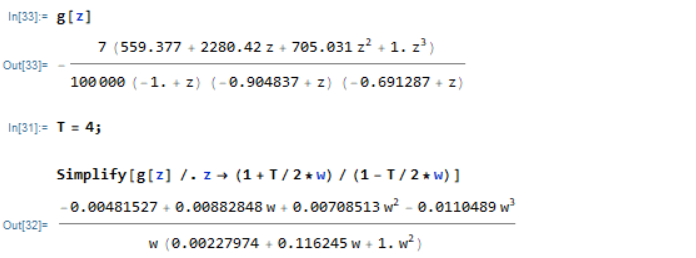

**Using c2d in matlab :**

Ts = 4;
Gp_d = c2d(Gp,Ts,'zoh')


Gp_d =
 
  -4.635e-05 z^2 - 0.0001652 z - 3.666e-05
  ----------------------------------------
     z^3 - 2.596 z^2 + 2.221 z - 0.6254
 
Sample time: 4 seconds
Discrete-time transfer function.



## Root Locus

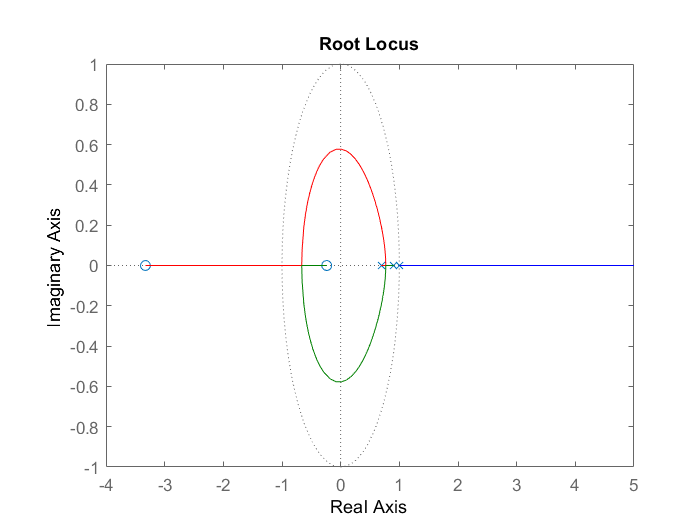

rlocus(Gp_d)

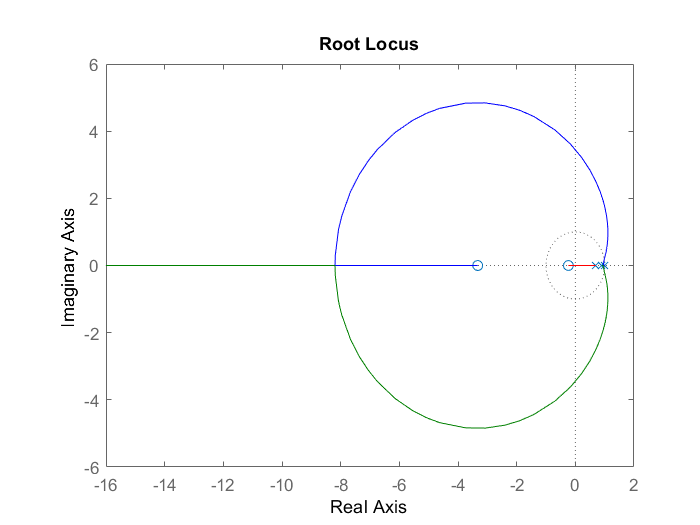

rlocus(-Gp_d)

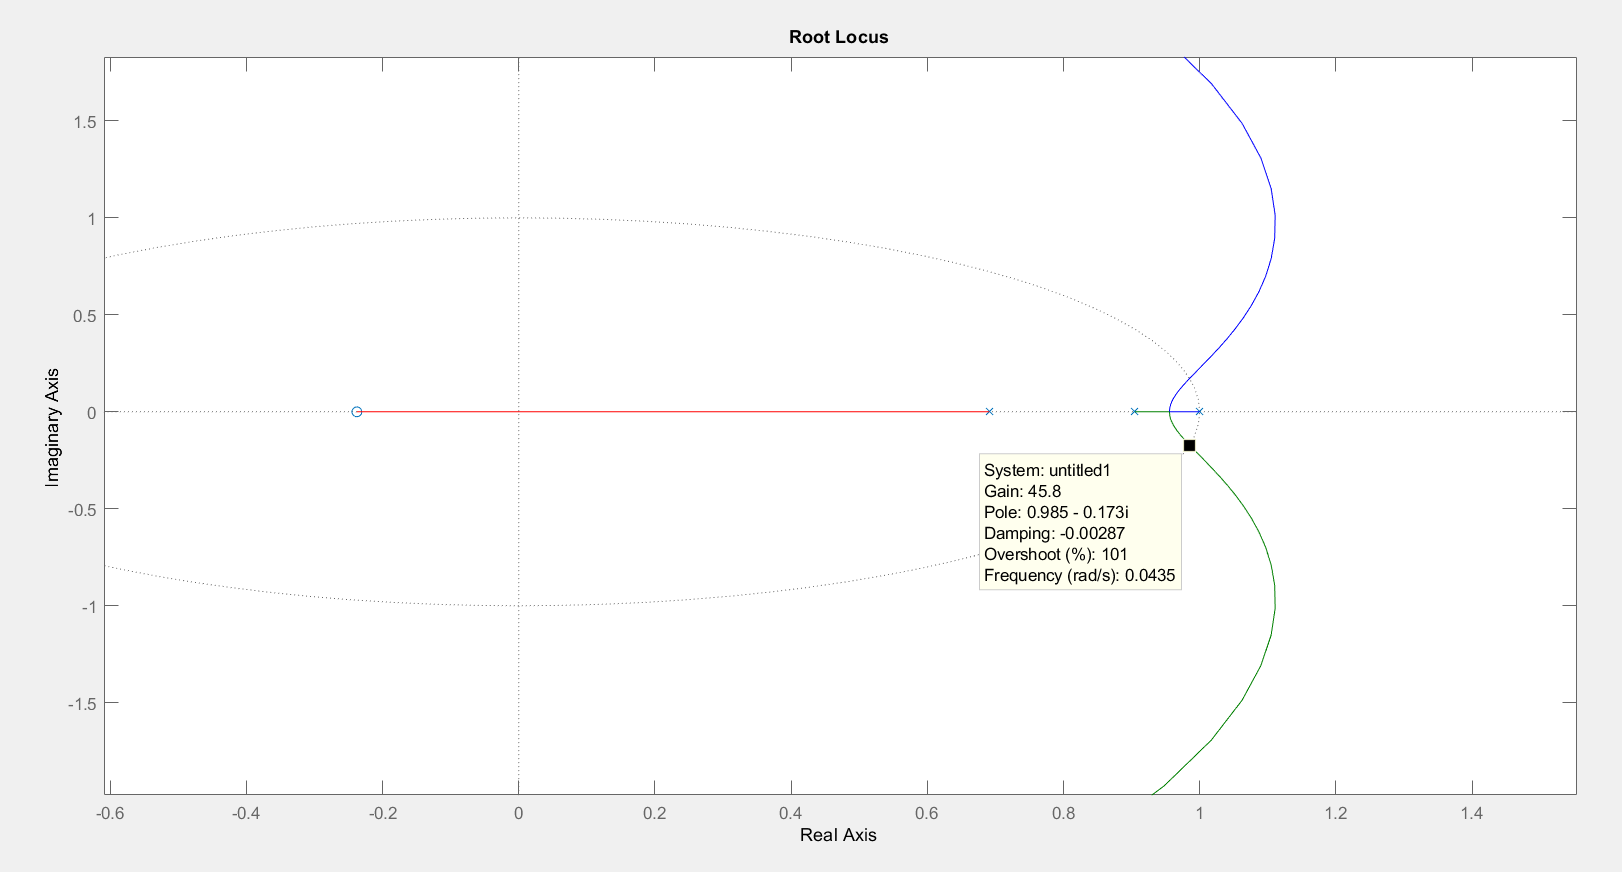

`Therefore => -45.8<k<0`

## `Bode plot ( z domain )`

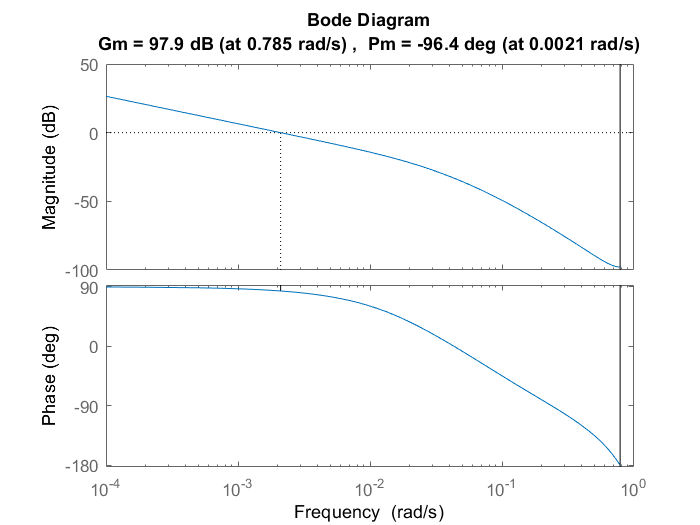

margin(Gp_d)

[Gm,Pm,Wgm,Wpm] = margin(Gp_d)

Gm = 7.8339e+04

Pm = -96.3569

Wgm = 0.7854

Wpm = 0.0021

## **Bode plot ( Frequency domian )**

Using Mathematica :


$$G\left\lbrack \text{w_}\right\rbrack :=\left(-4.635∗10ˆ-5∗zˆ2-0.0001652∗zˆ1-3.666∗10ˆ-5\right)/\left(zˆ3-2.596∗zˆ2+2.221∗z-0.6254\right)/\ldotp z\to \text{}\left(\left(T/2∗w+1\right)/\left(1-T/2∗w\right)\right)$$


= $\frac{0.0000048159-0.0000088798\text{}w-0.000007883\text{}w^2 +0.00001276\text{}w^3 }{0.0000077611-0.002297281\text{}w-0.116323\text{}w^2 -1.\text{}w^3 }$

num = [0.00001276 , -0.000007883 , -0.0000088798 , 0.0000048159];
den = [-1 , -0.116323 , -0.00229728 , 0.0000077611];
gw = tf(num,den)


gw =
 
  -1.276e-05 s^3 + 7.883e-06 s^2 + 8.88e-06 s - 4.816e-06
  -------------------------------------------------------
         s^3 + 0.1163 s^2 + 0.002297 s - 7.761e-06
 
Continuous-time transfer function.



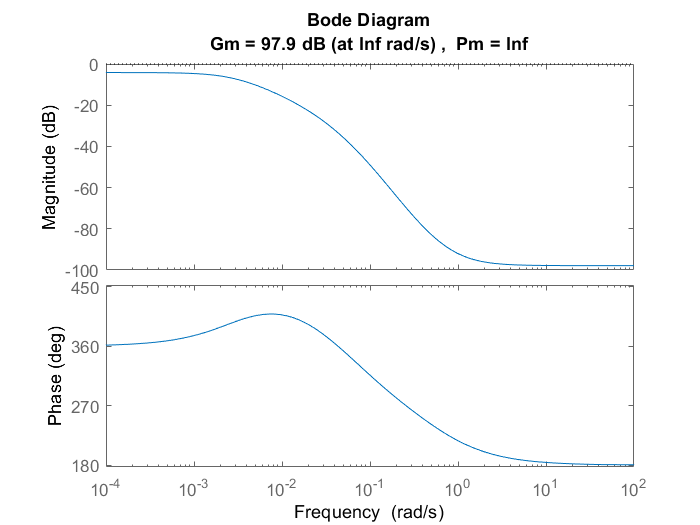

margin(gw)

[Gm,Pm,Wgm,Wpm] = margin(gw)

Gm = 7.8370e+04

Pm = Inf

Wgm = Inf

Wpm = NaN

# **Design a controler ( p5 )**

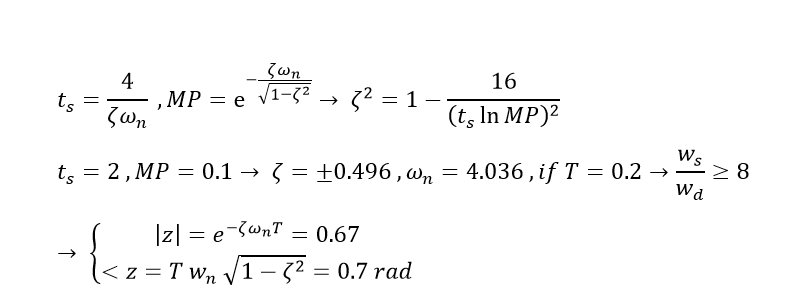

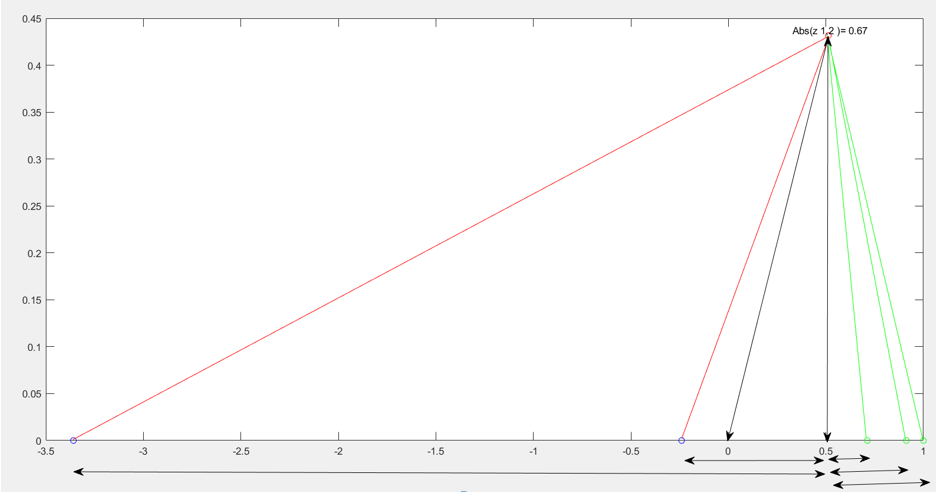

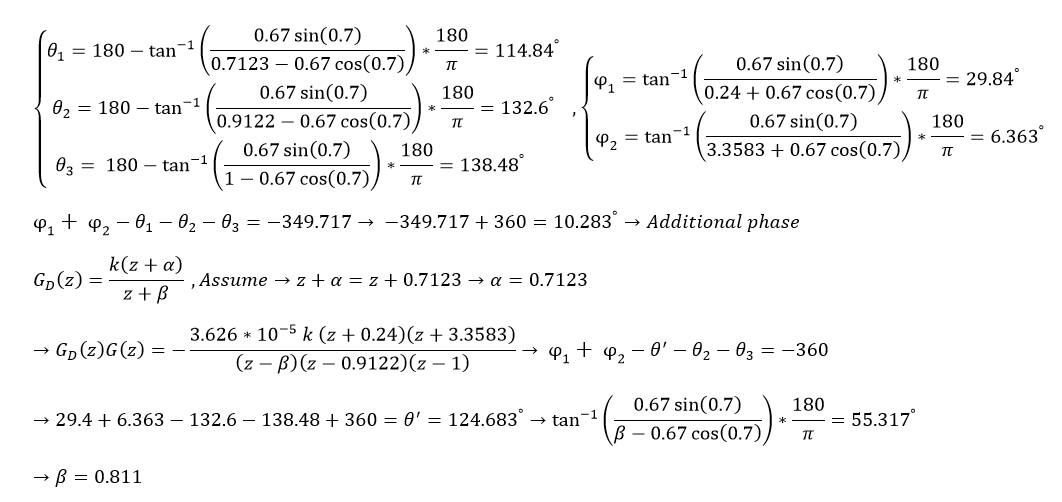

So, Reconstructing the Open loop Transfer function : Gp(z)*G(z) 

Ts=0.2;
GC =  tf(-3.626*10^-5*conv([1 0.24],[1 3.3583]),conv(conv([1,-1],[1,-0.9122]), [1,-0.811]),Ts)


GC =
 
  -3.626e-05 z^2 - 0.0001305 z - 2.923e-05
  ----------------------------------------
     z^3 - 2.723 z^2 + 2.463 z - 0.7398
 
Sample time: 0.2 seconds
Discrete-time transfer function.



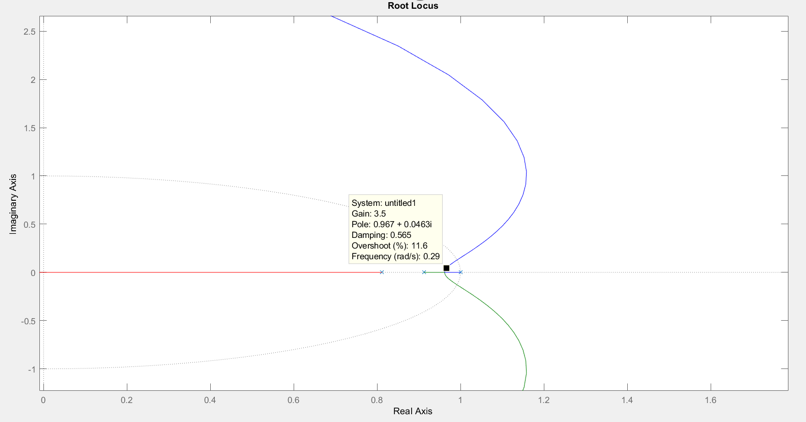

Decide to choose the controller coeffient form root locus

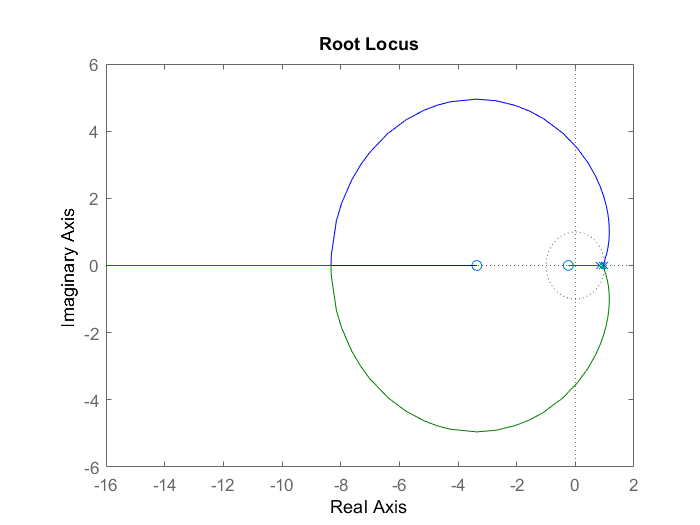

rlocus(-GC)

choosing k = -3.5, then plot the step response 

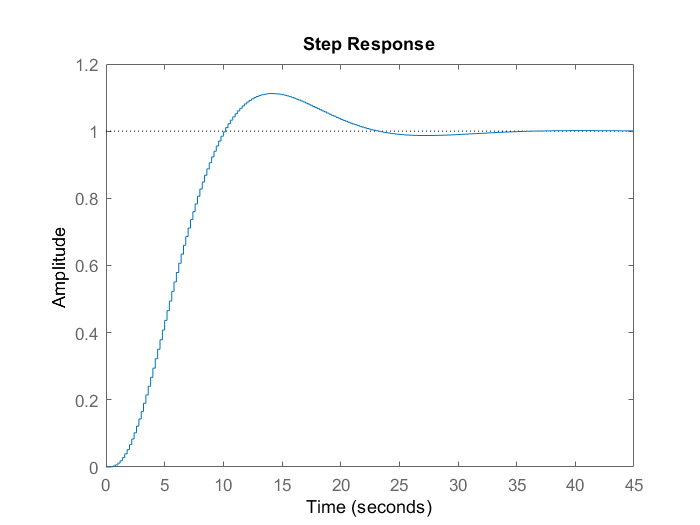

step(feedback(-3.5*GC,1))

stepinfo(step(feedback(-3.5*GC,1)))

ans = struct with fields:
        RiseTime: 31.8274
    SettlingTime: 105.9726
     SettlingMin: 0.9061
     SettlingMax: 1.1120
       Overshoot: 11.0364
      Undershoot: 0
            Peak: 1.1120
        PeakTime: 71



GC =
 
  -3.626e-05 z^2 - 0.0001305 z - 2.923e-05
  ----------------------------------------
     z^3 - 2.723 z^2 + 2.463 z - 0.7398
 
Sample time: 0.2 seconds
Discrete-time transfer function.



# **Comparing the features per plot(p6)**

## Bode plot (Frequency Domain)

 Using Mathematica ( Uncontrolled system )


$$G\left\lbrack \text{w_}\right\rbrack :=\left(-6.462\ast 10ˆ-9\ast zˆ2-2.57\ast 10ˆ-8\ast z-6.387\ast 10ˆ-9\right)/\left(zˆ3-2.977\ast zˆ2+2.954\ast z-0.9768\right)/\ldotp z\to \left(\left(T/2\ast w+1\right)/\left(1-T/2\ast w\right)\right)$$



$$=\frac{-1.6251\times {10}^{-9} \text{}w^3 +1.6441\times {10}^{-8} \text{}w^2 +4.85584\times {10}^{-7} \text{}w-0.00000487481}{1.\text{}w^3 +0.1171\text{}w^2 -0.007587\text{}w+0.02529}$$


Num_w_pre = [-1.6251*10^-9,1.6441*10^-8,4.85584*10^-7,-0.00000487481];
Den_w_pre = [1 , 0.1171 , -0.007587 , 0.02529];
Gp_w_pre = tf(Num_w_pre,Den_w_pre)


Gp_w_pre =
 
  -1.625e-09 s^3 + 1.644e-08 s^2 + 4.856e-07 s - 4.875e-06
  --------------------------------------------------------
          s^3 + 0.1171 s^2 - 0.007587 s + 0.02529
 
Continuous-time transfer function.



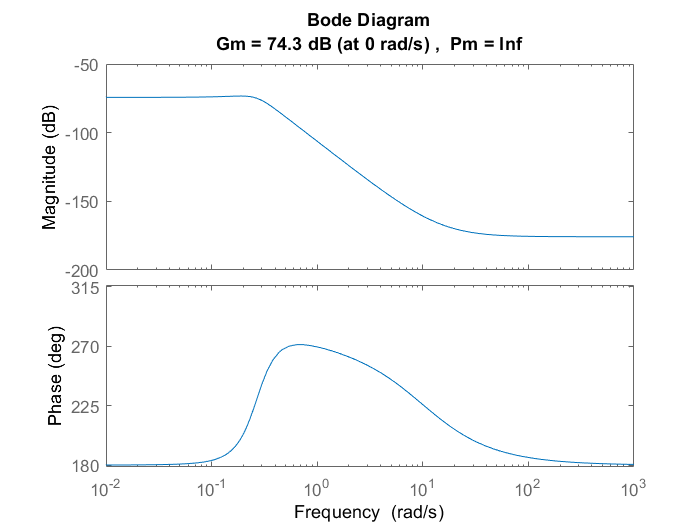

margin(Gp_w_pre)

[Gm,Pm,Wgm,Wpm] = margin(Gp_w_pre)

Gm = 5.1879e+03

Pm = Inf

Wgm = 0

Wpm = NaN

## root locus( Uncontrolled system )

Ts = 0.2;
Gp_d = c2d(Gp,Ts,'zoh')
rlocus(Gp_d)
rlocus(-Gp_d)

## 
$$\mathrm{Bode}\text{ }\mathrm{plot}\text{ }\left(\mathrm{Frequency}\text{ }\mathrm{Domain}\right)$$



$$\begin{array}{l}
\mathrm{Using}\text{ }\mathrm{Mathematica}\text{ }\left(\mathrm{Contolled}\text{ }\mathrm{system}\right)\\
G\left\lbrack \text{w_}\right\rbrack :=\text{}\left(-3.626∗10ˆ-5∗zˆ2-0.0001305∗z-2.923∗10ˆ-5\right)/\left(zˆ3-2.723∗zˆ2+2.463∗z-0.7398\right)/\ldotp z\to \left(T/2∗w+1\right)/\left(1-T/2∗w\right)\\
=\frac{-0.00000939\text{}w^3 +0.0001142\text{}w^2 +0.0026268\text{}w-0.028299}{1.\text{}w^3 +1.502498\text{}w^2 +0.48225\text{}5w+0.02887753}
\end{array}$$


Num_w_post = [-0.00000939,0.0001142,0.0026268,-0.028299]

Num_w_post =    -0.0000    0.0001    0.0026   -0.0283


Den_w_post = [1,1.502498,0.482255,0.02887753]

Den_w_post =     1.0000    1.5025    0.4823    0.0289


Gp_w_post = tf(Num_w,Den_w)


Gp_w_post =
 
  -9.39e-06 s^3 + 0.0001142 s^2 + 0.002627 s - 0.0283
  ---------------------------------------------------
         s^3 + 1.502 s^2 + 0.4823 s + 0.02888
 
Continuous-time transfer function.



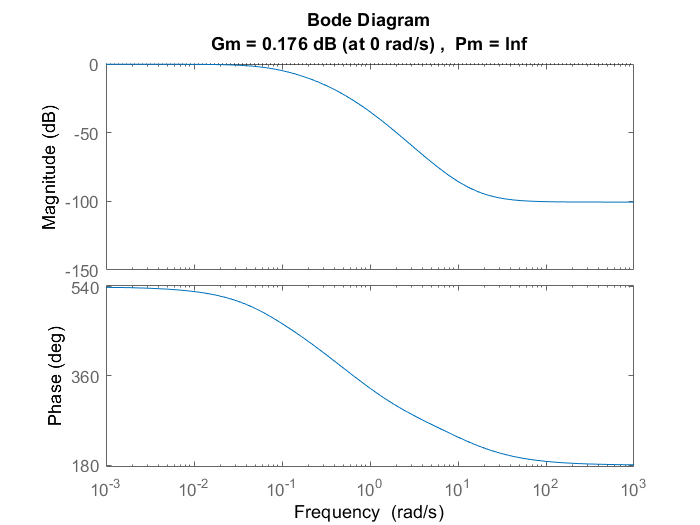

margin(Gp_w_post)

[Gm,Pm,Wgm,Wpm] = margin(Gp_w_post)

Gm = 1.0204

Pm = Inf

Wgm = 0

Wpm = NaN

## root locus( Controlled system )

rlocus(-GC)

# Designing a DeadBeat